# Transimpedance amplifier

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Dependencies include files rescale1.m, plethy.mat and Transimpedance1.slx

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter6/PPG'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Generate Data


%clear all
load('plethy.mat');
a1=rescale1([a;a;a;a;a;a;a;a;a;a]);
a2=5*(1-0.01*a1);
T=0.0001;
len=10*1/T+1;
a2q=zeros(1,len);
step=floor((1/T)/1000); %1kHz
%a2q(1:step:step*length(a2))=a2;
a2q1 = interp1(1/length(a):1/length(a):10,a2,0:T:10, 'linear','extrap');
a2q(1:step:length(a2q))= a2q1(1:step:length(a2q));
a2q(2:step:length(a2q))= a2q1(2:step:length(a2q));
a2q(3:step:length(a2q))= a2q1(3:step:length(a2q));
Irr1(:,1)=0:T:10; %time
Irr1(:,2)=a2q'; % irradiance



## Running simulation

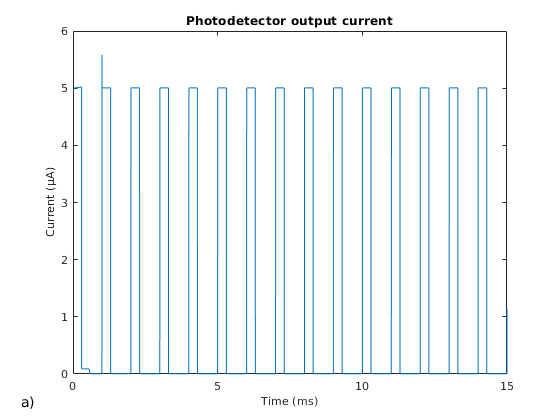


simOut = sim('Transimpedance1', 'CaptureErrors', 'on');
figure,plot(simOut.i_out.Time*1e3, -simOut.i_out.Data*1e6)
xlim([0,15])
xlabel('Time (ms)', 'FontSize', 10)
ylabel('Current (µA)', 'FontSize', 10)
title("Photodetector output current")
annonation_save('a)',"Fig6.14a.jpg", SAVE_FLAG);

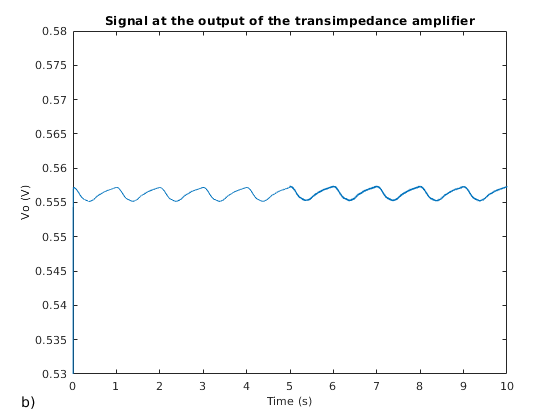


figure,plot(simOut.Vo.Time, simOut.Vo.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Vo (V)', 'FontSize', 10)
ylim([0.53,0.58])
title('Signal at the output of the transimpedance amplifier')
annonation_save('b)',"Fig6.14b.jpg", SAVE_FLAG);

%save('Transimp.mat','simOut')



